## Example from Robust Control note

clc
clear
s = tf('s');
M = [1/(2*s+1), 1, (s-2)/(2*s+4);
    -1, s/(s^2+s+1), 1/(s+1)^2 ;
    (3*s)/(s+5), -1/(4*s+1), 1];

W = logspace(-1,3,100);
SV = sigma(M, W);
spectral = zeros(1,length(W));
Ms = freqresp(M,W);
for i=1:length(W)
    spectral(i) = abs(eigs(Ms(:,:,i),1));
end

[bounds, muinfo] = mussv(frd(M,W),[1 1; 2 2]);

Points completed: 100/100


[VDelta,VSigma,VLmi] = mussvextract(muinfo);
VDelta.responsedata(:,:,:)

ans = ans(:,:,1) =

   0.4679 + 0.0376i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.2053 - 0.0570i  -0.1681 - 0.0489i
   0.0000 + 0.0000i   0.2915 + 0.0339i   0.2392 + 0.0308i


ans(:,:,2) =

   0.4691 + 0.0412i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.2042 - 0.0620i  -0.1664 - 0.0526i
   0.0000 + 0.0000i   0.2932 + 0.0377i   0.2394 + 0.0335i


ans(:,:,3) =

   0.4706 + 0.0452i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.2029 - 0.0675i  -0.1644 - 0.0564i
   0.0000 + 0.0000i   0.2951 + 0.0420i   0.2396 + 0.0364i


ans(:,:,4) =

   0.4723 + 0.0496i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.2013 - 0.0733i  -0.1623 - 0.0603i
   0.0000 + 0.0000i   0.2972 + 0.0469i   0.2399 + 0.0395i


ans(:,:,5) =

   0.4743 + 0.0544i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.1995 - 0.0795i  -0.1600 - 0.0643i
   0.0000 + 0.0000i   0.2995 + 0.0525i   0.2403 + 0.0428i


ans(:,:,6) =

   0.4766 + 0.0595i   0.0000 +

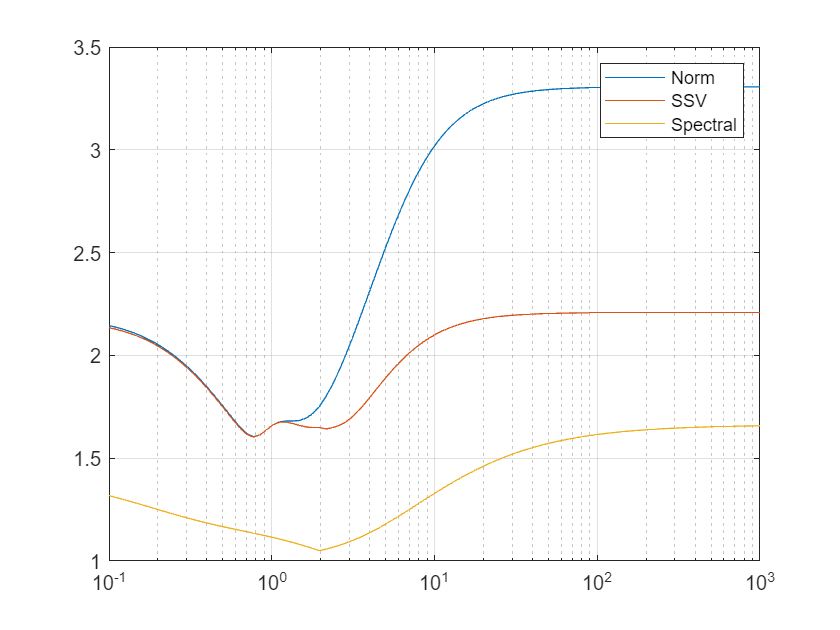

upperBound = bounds(1).ResponseData(:);

semilogx(W,max(SV),W,upperBound,W,spectral)
legend('Norm', 'SSV', 'Spectral')
grid on

## Our system with complex full blocks:


$$\Delta= 
\left[\matrix{\Delta_1 & 0 & 0 & 0 \cr 0 & \Delta_2 & 0 & 0 \cr
0 & 0 & \Delta_3 & 0 \cr 0 & 0 & 0 & \Delta_4}\right], \qquad \Delta_i \in \mathbb{C}, \quad i=1,2,3,4$$


clc
clear

s = tf('s');
M = [(1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0, 0, 0;
      0, (1.312*s^2 - 18.84*s - 5.127)/(s^3 + 2.764*s^2 + 18.97*s + 5.127), 0 , 0;
      0, 0, (1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0 ;
      0, 0, 0, (1.279*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031)];

W = logspace(-1,3,1000);
SV = sigma(M, W);
spectral = zeros(1,length(W));
Ms = freqresp(M,W);
for i=1:length(W)
    spectral(i) = abs(eigs(Ms(:,:,i),1));
end

bounds  = mussv(frd(M,W),[1 1; 1 1; 1 1; 1 1]);

Points completed: 1000/1000


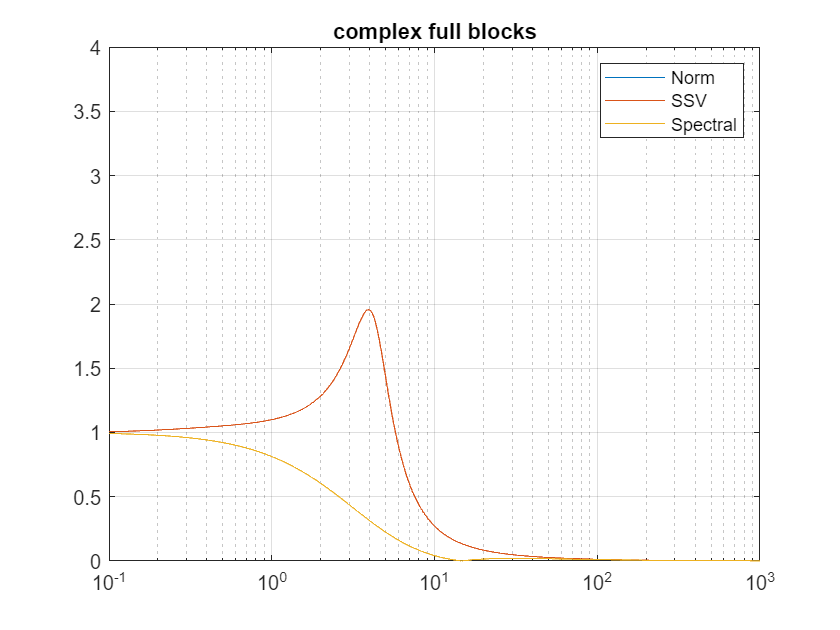


upperBound = bounds(1).ResponseData(:);

semilogx(W,max(SV),W,upperBound,W,spectral)
ylim([0;4])
legend('Norm', 'SSV', 'Spectral')
title('complex full blocks')
grid on

## Our system with one complex full blocks:


$$\Delta \in \mathbb{C}^{4\times 4}$$


clc
clear

s = tf('s');
M = [(1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0, 0, 0;
      0, (1.312*s^2 - 18.84*s - 5.127)/(s^3 + 2.764*s^2 + 18.97*s + 5.127), 0 , 0;
      0, 0, (1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0 ;
      0, 0, 0, (1.279*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031)];

W = logspace(-1,3,1000);
SV = sigma(M, W);
spectral = zeros(1,length(W));
Ms = freqresp(M,W);
for i=1:length(W)
    spectral(i) = abs(eigs(Ms(:,:,i),1));
end

bounds  = mussv(frd(M,W),[4,4]);

Points completed: 1000/1000


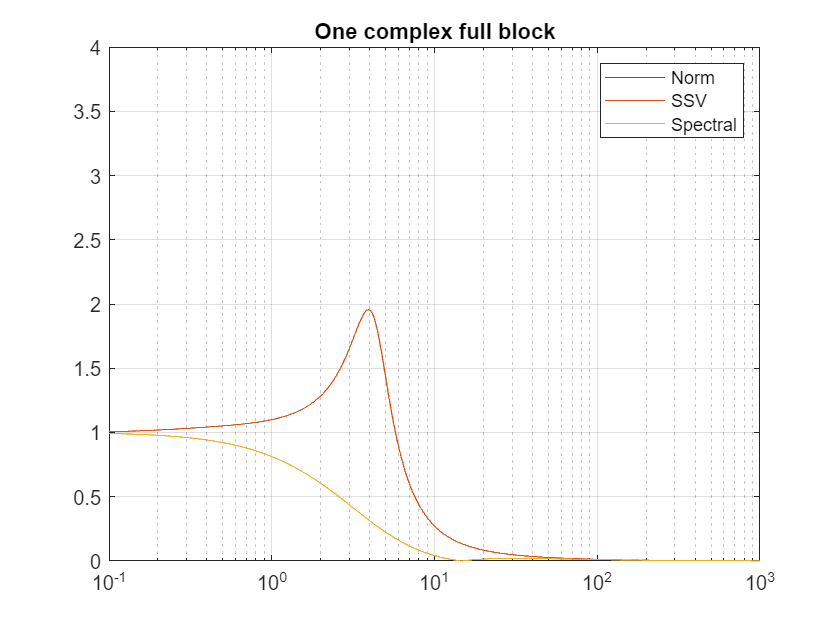


upperBound = bounds(1).ResponseData(:);

semilogx(W,max(SV),W,upperBound,W,spectral)
ylim([0;4])
legend('Norm', 'SSV', 'Spectral')
title('One complex full block')
grid on

## Our system with complex full blocks:


$$\Delta= 
\left[\matrix{\delta_1 & 0 & 0 & 0 \cr 0 & \delta_2 & 0 & 0 \cr
0 & 0 & \delta_3 & 0 \cr 0 & 0 & 0 & \delta_4}\right], \qquad \delta_i \in \mathbb{C}, \quad i=1,2,3,4$$


clc
clear

s = tf('s');
M = [(1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0, 0, 0;
      0, (1.312*s^2 - 18.84*s - 5.127)/(s^3 + 2.764*s^2 + 18.97*s + 5.127), 0 , 0;
      0, 0, (1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0 ;
      0, 0, 0, (1.279*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031)];

W = logspace(-1,3,100);
SV = sigma(M, W);
spectral = zeros(1,length(W));
Ms = freqresp(M,W);
for i=1:length(W)
    spectral(i) = abs(eigs(Ms(:,:,i),1));
end

[bounds,muinfo]  = mussv(frd(M,W),[1,1;1,1;2,2]);

Points completed: 100/100



[VDelta,VSigma,VLmi] = mussvextract(muinfo);
VDelta.responsedata(:,:,:)

ans = ans(:,:,1) =

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.9937 - 0.0047i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


ans(:,:,2) =

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.9926 - 0.0055i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


ans(:,:,3) =

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.9913 - 0.0066i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


ans(:,:,4) =

   0.000

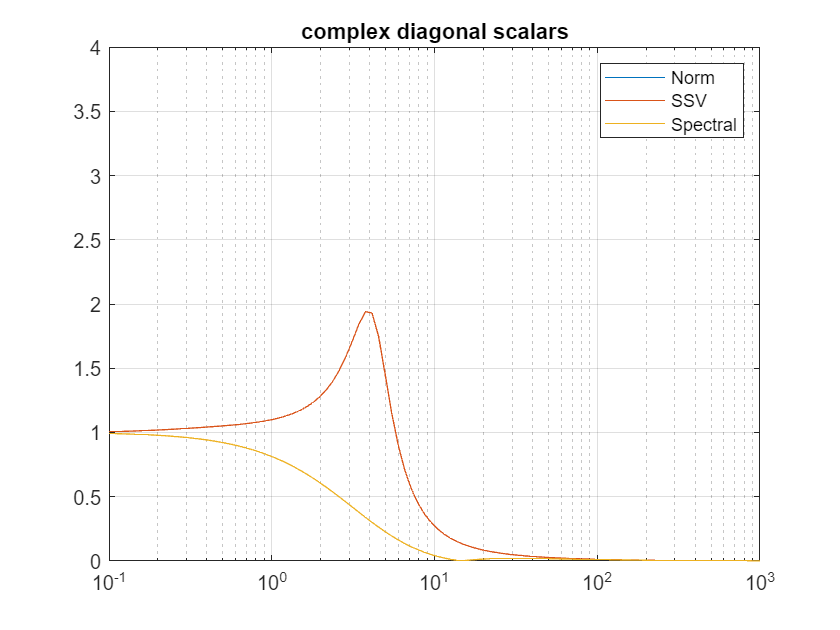

upperBound = bounds(1).ResponseData(:);

semilogx(W,max(SV),W,upperBound,W,spectral)
ylim([0;4])
legend('Norm', 'SSV', 'Spectral')
title('complex diagonal scalars')
grid on

## Our system with real diagonal pertubations:


$$\Delta= 
\left[\matrix{\delta_1 & 0 & 0 & 0 \cr 0 & \delta_2 & 0 & 0 \cr
0 & 0 & \delta_3 & 0 \cr 0 & 0 & 0 & \delta_4}\right], \qquad \delta_i \in \mathbb{R}, \quad i=1,2,3,4$$


clc
clear

s = tf('s');
M = [(1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0, 0, 0;
      0, (1.312*s^2 - 18.84*s - 5.127)/(s^3 + 2.764*s^2 + 18.97*s + 5.127), 0 , 0;
      0, 0, (1.28*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031), 0 ;
      0, 0, 0, (1.279*s^2 - 18.47*s - 5.031)/(s^3 + 2.757*s^2 + 18.6*s + 5.031)];

W = logspace(-1,3,1000);
SV = sigma(M, W);
spectral = zeros(1,length(W));
Ms = freqresp(M,W);
for i=1:length(W)
    spectral(i) = abs(eigs(Ms(:,:,i),1));
end

bounds  = mussv(frd(M,W),[-1,0;-1,0;-1,0;-1,0]);

Points completed: 1000/1000


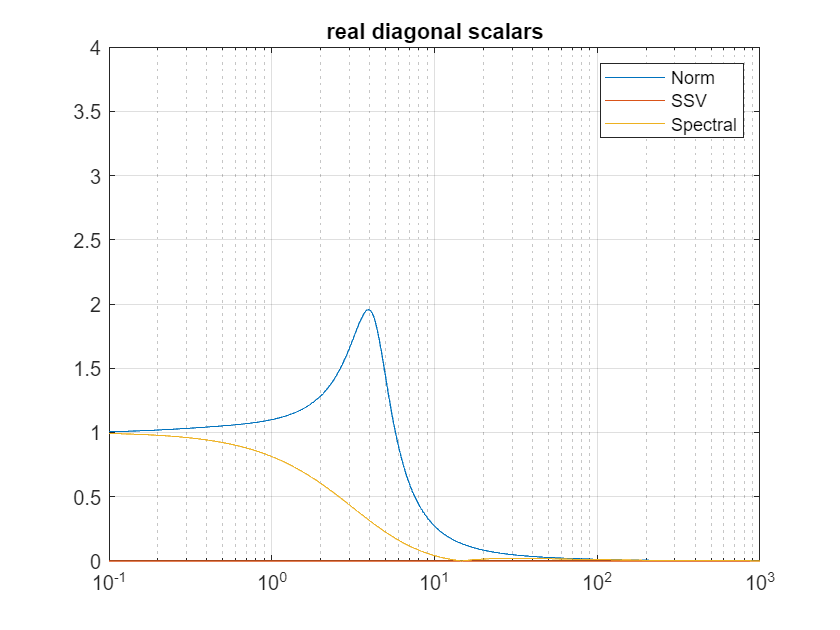


upperBound = bounds(1).ResponseData(:);

semilogx(W,max(SV),W,upperBound,W,spectral)
ylim([0;4])
legend('Norm', 'SSV', 'Spectral')
title('real diagonal scalars')
grid on